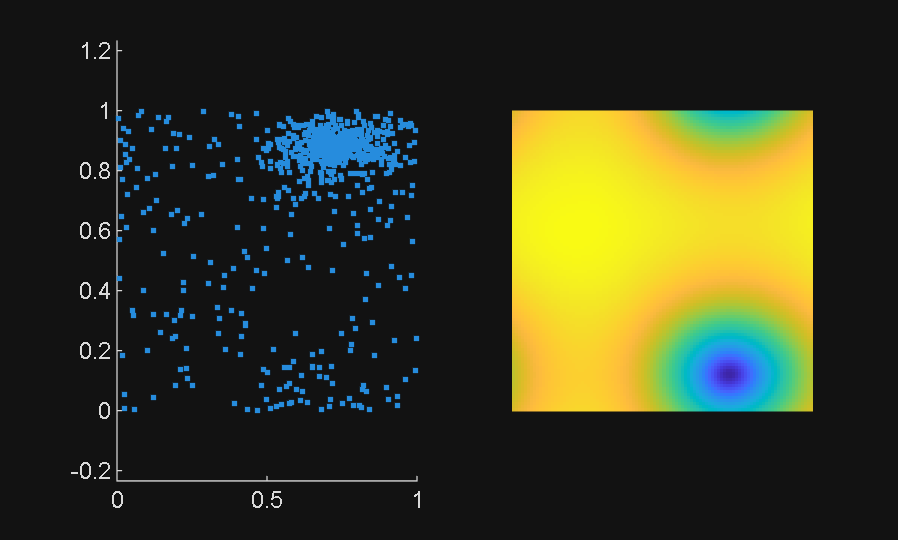

NumP = 1000;
dt = .001;
SpR = 100;
alpha = .3;

R = rand(NumP,2)*.5+.5;
V = rand(NumP,2).*2-1;
T = R(:,1).*0;

subplot(1,2,1)
rho = accumarray(ceil(SpR*R),ones([size(R,1) 1]));
Ip = imshow(rho,InitialMagnification=200);
Sp = scatter(R(:,1),R(:,2),'.');
xlim([0 1])
ylim([0 1])
axis equal
subplot(1,2,2)
I = imshow(mat2gray(rho.*0),InitialMagnification=100);
hold on
colormap parula;
drawnow;


b   = (rho);
psi = (0*rho);

Err = b-imfilter(psi,fspecial("laplacian"),"circular","conv");
psi = psi-alpha*(Err);
Errl = Err;
Err = b-imfilter(psi,fspecial("laplacian"),"circular","conv");
psi = psi-alpha*(Err);

for i=1:1000
    for j = 1:1000
    Errl = Err;
    Err = b-imfilter(psi,fspecial("laplacian"),"circular","conv");
    psi = psi-alpha*(Err);
    Ep = sum(sum(abs(Errl-Err)));
    alpha = (.3*Ep+3)/(Ep+1);
    end
    [psiDx,psiDy] = gradient(psi);
    
    IndR = sub2ind([SpR SpR],ceil(SpR*R(:,1)),ceil(SpR*R(:,2)));
    V = V - 100*dt.*[psiDy(IndR) psiDx(IndR)];
    R = R + dt.*V;
    R = mod(R,1);
    b = accumarray(ceil(SpR*R),ones([size(R,1) 1]),[SpR SpR]);
    b = imgaussfilt(b,2,padding="circular");
    set(Sp,'XData',R(:,1),'YData',R(:,2));
    % set(Ip,'CData',5*(rho))
    set(I,'CData',mat2gray(gather(psi))');
    drawnow;
end